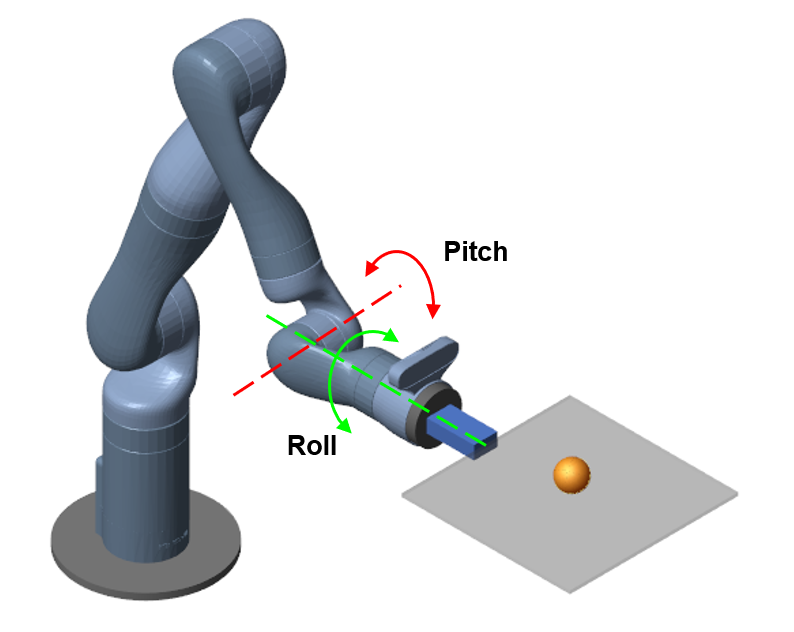

open_system("RL_train_simulation")

## 输入：

    [横摆角速度，偏航角，车速，左侧地面附着系数，右侧地面附着系数]

## 输出：

    [制动力，方向盘转角]

    未来可以考虑加入：制动历史，转向历史，车速历史，对开路面标志信号的历史，各个轮速的历史等

nObs = 5;  % Number of dimension of the observation space
nAct = 2;   % Number of dimension of the action space

obsInfo = rlNumericSpec([nObs 1]);

actInfo = rlNumericSpec([nAct 1]);
actInfo.LowerLimit = -1;
actInfo.UpperLimit = 1;

Create the Simulink environment interface using the observation and action specifications. For more information on creating Simulink environments, see [`rlSimulinkEnv`](docid:rl_ref#mw_12cc40dc-3191-4a23-af71-1625696c1a14).

mdl = "RL_train_simulation";
blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);

Specify a reset function for the environment using the `ResetFcn` parameter. 

env.ResetFcn = @kinovaResetFcn;

This reset function (provided at the end of this example) randomly initializes the initial x and y positions of the ball with respect to the center of the plate. For more robust training, you can also randomize other parameters inside the reset function, such as the mass and radius of the ball.

Specify the sample time `Ts` and simulation time `Tf`.

Ts = 0.01;
Tf = 10;

## Create Agent

The agent in this example is a soft actor-critic (SAC) agent. SAC agents use one or two parametrized Q-value function approximators to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter). For more information on SAC agents, see [Soft Actor-Critic Agents](docid:rl_ug#mw_66993d46-0fa5-41fa-9b73-d3caf6f9e649).

The SAC agent in this example uses two critics. To model the parametrized Q-value functions within the critics, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value). For more information on creating deep neural networks for reinforcement learning agents, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

The actor and critic networks are initialized randomly. Ensure reproducibility by fixing the seed of the random generator.

rng(0)

Define each network path as an array of layer objects. Assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel.

% Define the network paths.
observationPath = [
    featureInputLayer(nObs,Name="observation")
    concatenationLayer(1,2,Name="concat")
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(1,Name="QValueOutLyr")
    ];
actionPath = featureInputLayer(nAct,Name="action");

Assemble `dlnetwork` object.

criticNet = dlnetwork;
criticNet = addLayers(criticNet, observationPath);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"action","concat/in2");

View the critic neural network.

plot(criticNet)

Display the number of weights.

summary(initialize(criticNet))

Create the critic approximators using `rlQValueFunction`. When using two critics, a SAC agent requires them to have different initial parameters. Initialize the networks separately to make sure that their initial weights are different.

critic1 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation");
critic2 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo, ...
    ObservationInputNames="observation");

Soft Actor-critic agents use a parametrized stochastic policy over a continuous action space, which is implemented by a continuous Gaussian actor. 

This actor takes an observation as input and returns as output a random action sampled from a Gaussian probability distribution.

To approximate the mean values and standard deviations of the Gaussian distribution, you must use a neural network with two output layers, each having as many elements as the dimension of the action space. One output layer must return a vector containing the mean values for each action dimension. The other must return a vector containing the standard deviation for each action dimension.

Since standard deviations must be nonnegative, use a softplus or ReLU layer to enforce nonnegativity. The SAC agent automatically reads the action range from the `UpperLimit` and `LowerLimit` properties of `actInfo` (which is used to create the actor), and then internally scales the distribution and bounds the action. Therefore, do not add a `tanhLayer` as the last nonlinear layer in the mean output path.

Define each network path as an array of layer objects, and assign names to the input and output layers of each path.

% Create the actor network layers.
commonPath = [
    featureInputLayer(nObs,Name="observation")
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer(Name="commonPath")
    ];
meanPath = [
    fullyConnectedLayer(32,Name="meanFC")
    reluLayer
    fullyConnectedLayer(nAct,Name="actionMean")
    ];
stdPath = [
    fullyConnectedLayer(nAct,Name="stdFC")
    reluLayer
    softplusLayer(Name="actionStd")
    ];

Assemble `dlnetwork` object.

actorNet = dlnetwork;
actorNet = addLayers(actorNet,commonPath);
actorNet = addLayers(actorNet,meanPath);
actorNet = addLayers(actorNet,stdPath);
actorNet = connectLayers(actorNet,"commonPath","meanFC/in");
actorNet = connectLayers(actorNet,"commonPath","stdFC/in");

View the actor neural network.

plot(actorNet)

Initialize network and display the number of weights.

actorNet = initialize(actorNet);
summary(actorNet)

Create the actor function using `rlContinuousGaussianActor`.

actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
    ObservationInputNames="observation", ...
    ActionMeanOutputNames="actionMean", ...
    ActionStandardDeviationOutputNames="actionStd");

The SAC agent in this example trains from an experience buffer of maximum capacity 1e6 by randomly selecting mini-batches of size 256. The fact that the discount factor is 0.99, that is very close to 1, means that the agent keeps more into account long term rewards (a discount factor closer to 0 would instead place a heavier discount on future rewards, therefore encouraging short term ones). For a full list of SAC hyperparameters and their descriptions, see [`rlSACAgentOptions`](docid:rl_ref#mw_378cf35c-0c56-448f-a836-4c236af12954).

Specify the agent hyperparameters for training. 

agentOpts = rlSACAgentOptions( ...
    SampleTime=Ts, ...
    TargetSmoothFactor=1e-3, ...    
    ExperienceBufferLength=1e6, ...
    MiniBatchSize=256, ...
    NumWarmStartSteps=256*10, ...
    DiscountFactor=0.99);

For this example the actor and critic neural networks are updated using the Adam algorithm with a learn rate of 1e-4 and gradient threshold of 1. Specify the optimizer parameters.

agentOpts.ActorOptimizerOptions.Algorithm = "adam";
agentOpts.ActorOptimizerOptions.LearnRate = 1e-3;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;

for ct = 1:2
    agentOpts.CriticOptimizerOptions(ct).Algorithm = "adam";
    agentOpts.CriticOptimizerOptions(ct).LearnRate = 1e-3;
    agentOpts.CriticOptimizerOptions(ct).GradientThreshold = 1;
end

Create the SAC agent.

agent = rlSACAgent(actor,[critic1,critic2],agentOpts);

## Train Agent

To train the agent, first specify the training options using [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0). For this example, use the following options:

- Run each training for at most 6000 episodes, with each episode lasting at most `floor(Tf/Ts)` time steps.

- Stop training when the evaluation of the greedy policy exceeds 700.

- To speed up training set the `UseParallel` option to `true`, which requires Parallel Computing Toolbox™ software. If you do not have the software installed set the option to `false`.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=6000, ...
    MaxStepsPerEpisode=floor(Tf/Ts), ...
    ScoreAveragingWindowLength=100, ...
    Plots="training-progress", ...
    SimulationStorageType="file",...
    StopTrainingCriteria="EvaluationStatistic", ...
    StopTrainingValue=700, ...
    UseParallel=true);

You can log training data to disk using the [`rlDataLogger`](docid:rl_ref#mw_3de067fc-ffdf-45f9-9a2b-439d9463a9cc) function. For this example, log the episode experience and actor and critic function losses. The functions `logAgentLearnData` and `logEpisodeData` are defined at the end of this Live Script. For more information see [Log Training Data To Disk](docid:rl_ug#mw_19d564c5-28d0-4c88-9bc5-64ac788f2116).

logger = rlDataLogger();
logger.AgentLearnFinishedFcn = @logAgentLearnData;
logger.EpisodeFinishedFcn    = @(data) logEpisodeData(data);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.


% Evaluate the performance of the greedy policy every 25 training
% episodes, averaging the cumulative reward of 5 simulations.
evaluator = rlEvaluator(EvaluationFrequency=25,NumEpisodes=5);
% train
trainResult = train(agent,env,trainOpts,Logger=logger,Evaluator=evaluator);

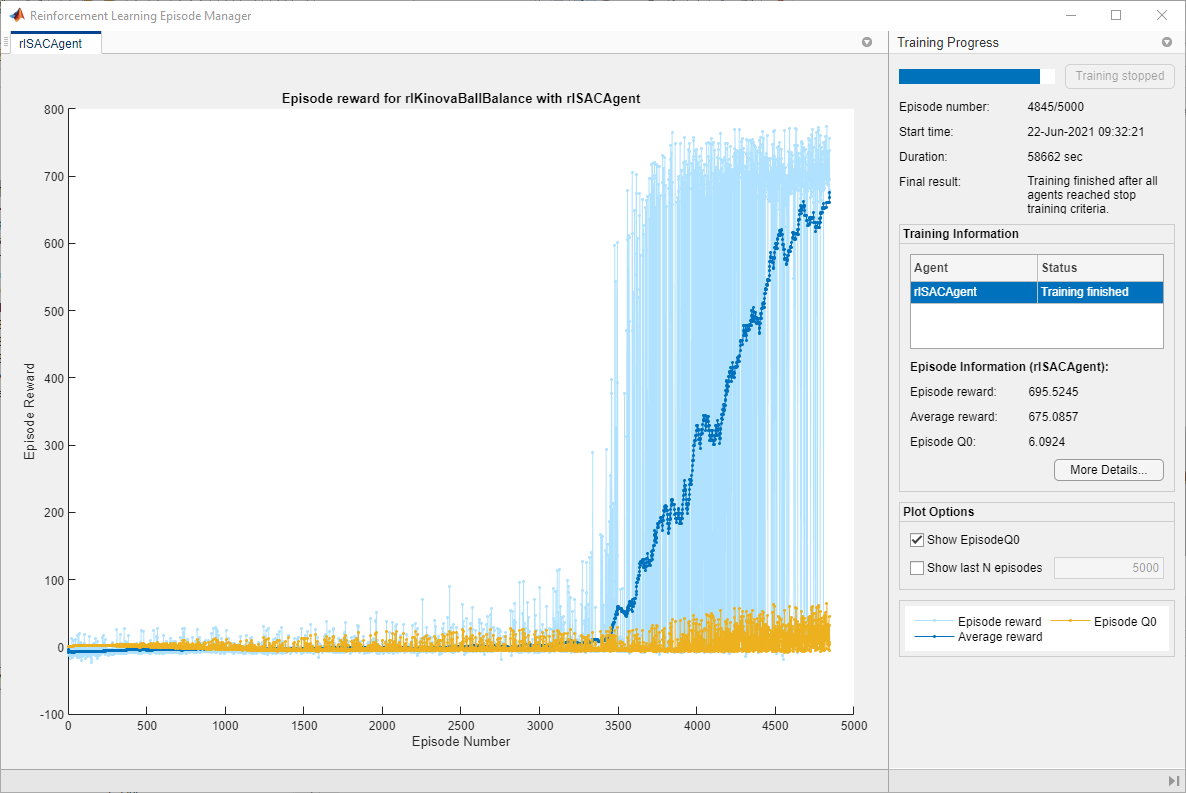

function in = kinovaResetFcn(in)
  
end

## Data Logging Functions

function dataToLog = logAgentLearnData(data)
% This function is executed after completion
% of the agent's learning subroutine

dataToLog.ActorLoss = data.ActorLoss;
dataToLog.CriticLoss = data.CriticLoss;
end

function dataToLog = logEpisodeData(data)
% This function is executed after the completion of an episode

dataToLog.Experience = data.Experience;

end

*Copyright 2021-2024 The MathWorks, Inc.*